# Integração Numérica 

#### Regra dos Trapézios


$$A_{TR}=\frac{h}{2}[f(x_{0})+2(f(x_{1})+f(x_{2})+\cdots+f(x_{m-1}))+f(x_{m})]$$


onde $h=\frac{b-a}{m}$.

Exemplo 1: Resolva a integral $\displaystyle \int_{0}^{1}e^{-x^{2}} dx$ para as seguintes subdivisões $m=1$ e $m=2$ e $m=4$.

Graficamente:

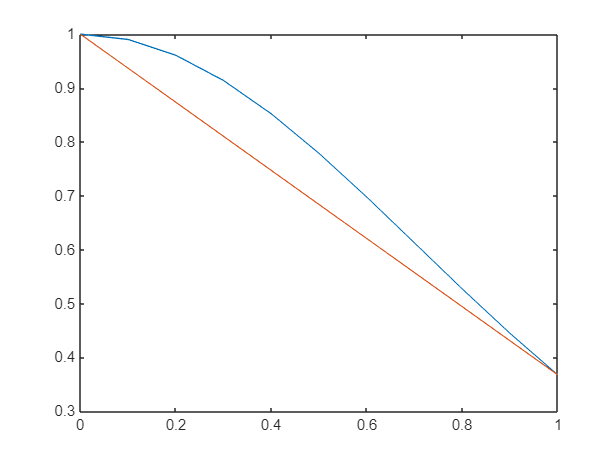

x =0:0.1:1;
y = fun(x);
p = polyfit([0 1],[fun(0) fun(-1)],1); %aproximar por uma intepolação linear sobre os pontos 0 e 1
f = polyval(p,x);
plot(x,y)
hold on
plot(x,f)
hold off

Implementações:

Regra Trapézio sem repetição:

m = 1; %x = [x0 x1 ... xm]
x0 = 0; %x0 = a
x1 = 1; %x1 = b
h = (x1-x0)/m;
AT = (h/2)*(fun(x0)+fun(x1))

AT = 0.6839

Regra Trapézio Repetida para $m=2$: 

m = 2; %x = [x0 x1 ... xm]
x0 = 0; %x0 = a
x1 = 1; %x1 = b
h = (x1-x0)/m;
AT = (h/2)*(fun(x0)+fun(x1))

AT =    0.341969860292861


Regra Trapézio Repetida para $m=4$:

m = 4; %x = [x0 x1 ... xm]
x0 = 0; %x0 = a
x1 = 1; %x1 = b
h = (x1-x0)/m;
AT = (h/2)*(fun(x0)+fun(x1))

AT =    0.170984930146430


Regra Geral para $m$ subdivisões:

clear
format long

m = 4;          
x0 = 0;        
x1 = 1;          
h = (x1 - x0)/m;  % Tamanho do passo

% Gera os pontos x = [x0, x1, ..., xm]
x = x0:h:x1;      

% Avalia a função em todos os pontos
y = fun(x);     

% Regra do Trapézio Generalizada (para m subdivisões)
AT = (h/2) * (y(1) + 2*sum(y(2:end-1)) + y(end))

AT =    0.742984097800381


Usando comando do matlab, **trapz()**


$$m=1$$


clear
x = [0 1];
y = [fun(0) fun(1)];
A = trapz(x,y)

A =    0.683939720585721



$$m=2$$


clear
x = 0:0.5:1;
y = [fun(0), fun(0.5), fun(1)];
A = trapz(x, y);
disp(A)

   0.731370251828563




$$m=4$$


clear
clear
x = 0 : 0.25 : 1;
y = [fun(0), fun(0.25), fun(0.50), fun(0.75), fun(1)];

A = trapz(x, y);
disp(A)

   0.742984097800381




$$m=100$$


clear
x = 0 : 0.01 : 1;
y = fun(x);

A = trapz(x, y);
disp(A)

   0.746818001467970



#### Regra 1/3 de Simpson


$$A_{SR}=\frac{h}{3}[f(x_{0})+4(f(x_{1})+f(x_{3})+\cdots+f(x_{2m-1}))+2(f(x_{2})+f(x_{4})+\cdots+f(x_{2m-2}))+f(x_{2m})]$$


Exemplo 1: Resolva a integral $\displaystyle \int_{0}^{1}e^{-x^{2}} dx$ para as seguintes subdivisões $m=2$ e $m=4$ e $m=6$.

Graficamente:

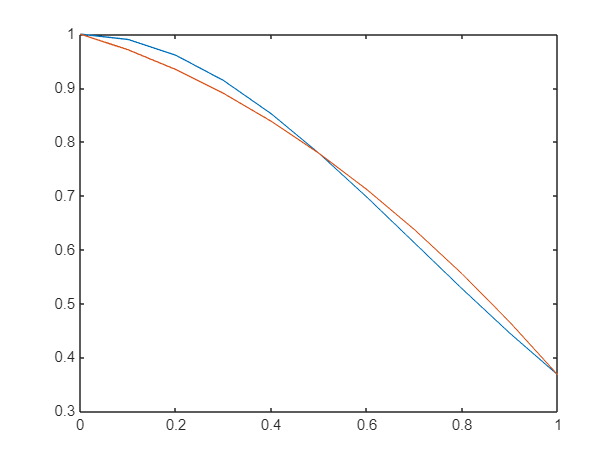

x =0:0.1:1;
y = fun(x);
p = polyfit([0 0.5 1],[1 fun(0.5) fun(1)],2); %aproximar por uma intepolação linear sobre os pontos 0 e 1
f = polyval(p,x);
plot(x,y)
hold on
plot(x,f)
hold off

Regra 1/3 de Simpson sem repetição ($m=2$): $x_{0}=a, \ x_{1}=x_{0}+h, \ x_{2}=x_{0}+2h=b$

a = 0; %[x0 x1 x2]
b = 1;
m = 2;
h = (b-a)/m;
As = (h/3)*(fun(a)+4*fun(a+h)+fun(a+2*h))

As =    0.747180428909510


Regra 1/3 de Simpson para $m=4$:


$$x_{0}=a, \ x_{1}=x_{0}+h, \ x_{2}=x_{0}+2h,  \ x_{3}=x_{0}+3h,  \ x_{4}=x_{0}+4h=b$$


clear
m = 4;
a = 0; %x0
b = 1; %x4
h = (b-a)/m;
As = (h/3)*(fun(a)+4*(fun(a+h)+fun(a+3*h)) + 2*fun(a+2*h)+fun(b))

As =    0.746855379790987


Regra Geral para m subdivisões:

clear
a = 0;
b = 1;
m = 10; %subdivisões
h = (b-a)/m;
s1 = 0;
s2 = 0;
x = 0:h:b;
for i = 1:(m/2)
    s1 = s1 + fun(a+(2*i-1)*h); %soma os valores da função para os pontos intermediários de indíces ímpares
end
for i = 1:(m/2)-1
    s2 = s2 + fun(a+(2*i)*h); %soma os valores da função para os pontos intermediários de indíces pares
end
ATSR = (h/3)*(fun(a) + 4*s1 + 2*s2 + fun(b));
fprintf("%f",ATSR)

0.746825

dy = dfun4(x);
maximo = norm(dy, inf);
etr = m*h^5*maximo/(2*90)

etr =      6.666666666666667e-06


**Quadratura Gaussina** (ordem 1 -  $G_{1}(f)$)


$$G_{1}(f) =\frac{(b-a)}{2}\left( f\left(\frac{a+b}{2} - \frac{b-a}{2\sqrt{3}}\right)  + f\left(\frac{a+b}{2} + \frac{b-a}{2\sqrt{3}}   \right)     \right)$$


Exemplo 1: Resolva a integral $\displaystyle \int_{0}^{1}e^{-x^{2}} dx$ para as seguintes subdivisões.

clear
a = 0;
b = 1;
x0 = ((a+b)/2) - (b-a)/(2*sqrt(3));
x1 = ((a+b)/2) + (b-a)/(2*sqrt(3));

G1 = ((b-a)/2) * (fun(x0)+fun(x1))

G1 =    0.746594688282860


Comando integral do matlab:

clear
 f = @(x) exp(-x.^2)

f = function_handle with value:
    @(x)exp(-x.^2)


 Q = integral(f,0,1)

Q =    0.746824132812427


function f = fun(x)
    f = exp(-x.^2);
end
function f = dfun4(x)
    f = 12.*exp(-x.^2) - 48*x.^2.*exp(-x.^2) + 16*x.^4.*exp(-x.^2);
end